data = readtable('emotion_dataset.csv');

features = data{:,2:end};        % All feature columns
labels = categorical(data{:,1}); % Convert label column to categorical

features = normalize(features);

cv = cvpartition(labels, 'HoldOut', 0.3);
trainIdx = training(cv);
testIdx = test(cv);

X_train = features(trainIdx, :);
X_test = features(testIdx, :);
y_train = labels(trainIdx);
y_test = labels(testIdx);

svm = fitcecoc(X_train, y_train);

pred_svm = predict(svm, X_test);

acc_svm = mean(pred_svm == y_test) * 100;

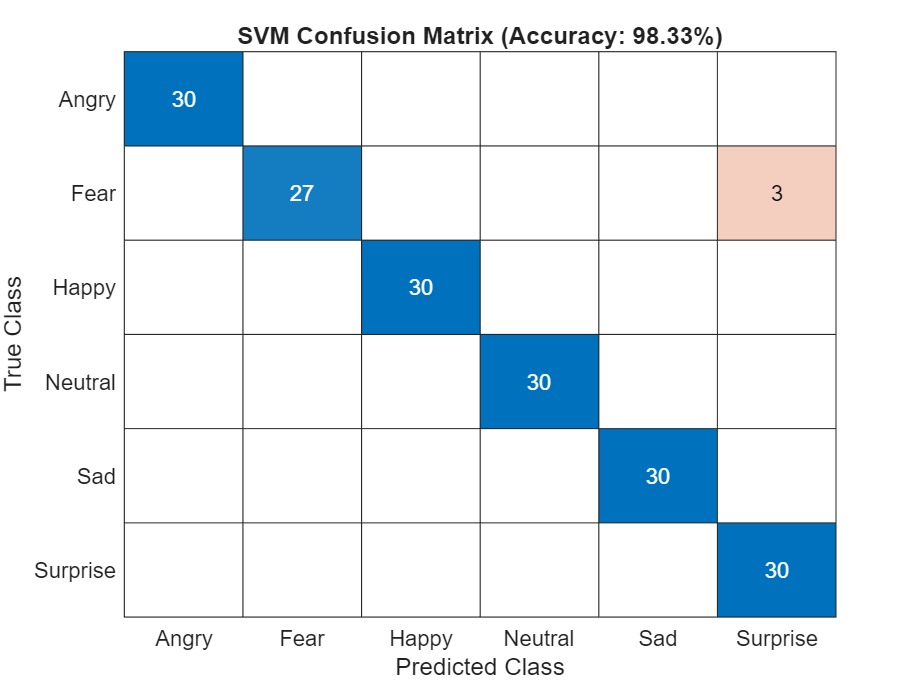

figure;
confusionchart(y_test, pred_svm);
title(sprintf('SVM Confusion Matrix (Accuracy: %.2f%%)', acc_svm));

tree = fitctree(X_train, y_train);

pred_tree = predict(tree, X_test);

acc_tree = mean(pred_tree == y_test) * 100;

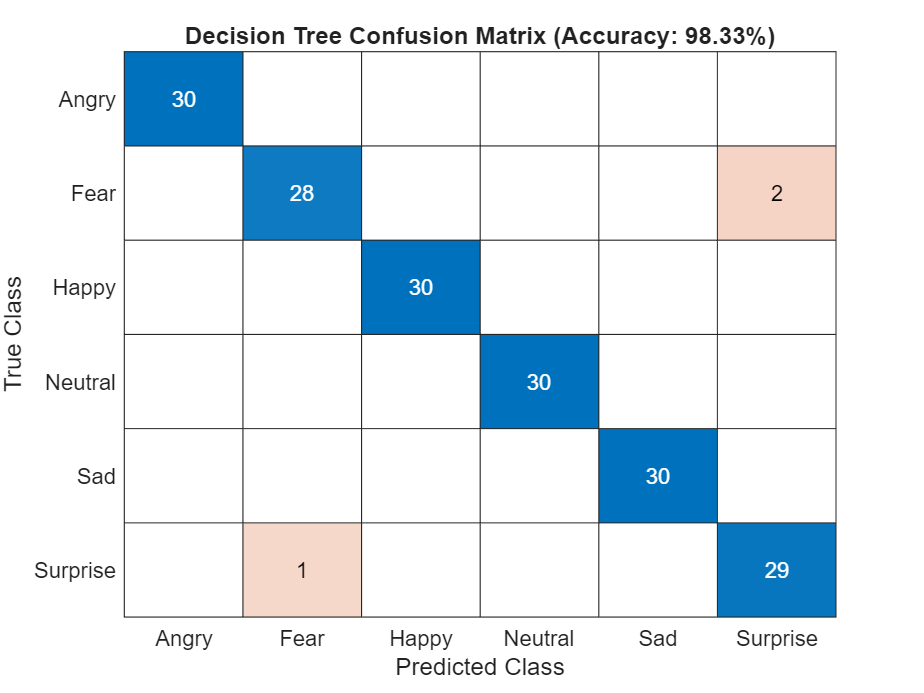

figure;
confusionchart(y_test, pred_tree);
title(sprintf('Decision Tree Confusion Matrix (Accuracy: %.2f%%)', acc_tree));

knn = fitcknn(X_train, y_train, 'NumNeighbors', 5, 'Distance', 'euclidean');

pred_knn = predict(knn, X_test);

acc_knn = mean(pred_knn == y_test) * 100;

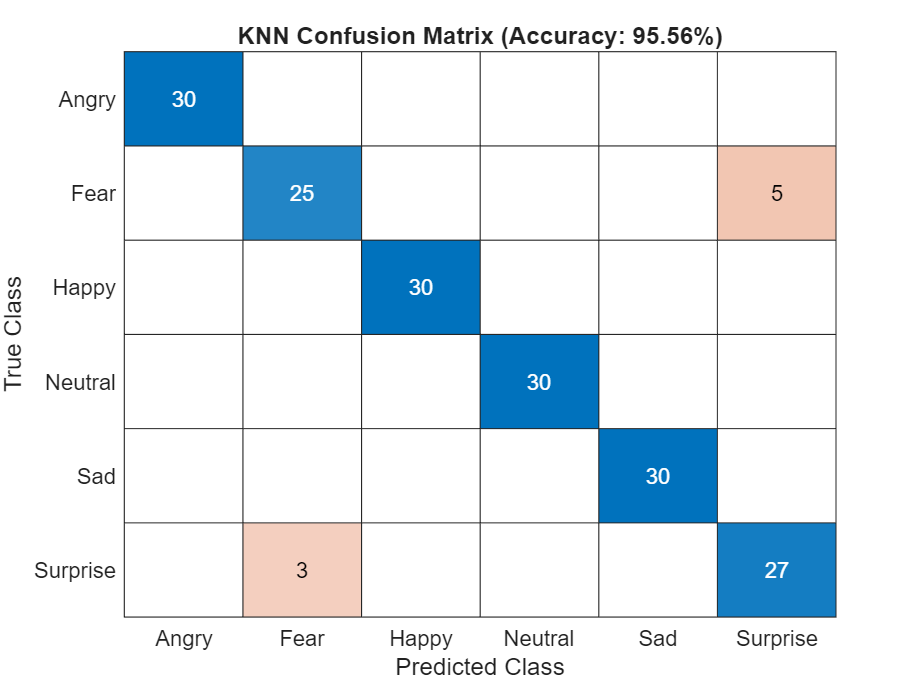

figure;
confusionchart(y_test, pred_knn);
title(sprintf('KNN Confusion Matrix (Accuracy: %.2f%%)', acc_knn));

ens = fitcensemble(X_train, y_train, 'Method', 'Bag');

pred_ens = predict(ens, X_test);

acc_ens = mean(pred_ens == y_test) * 100;

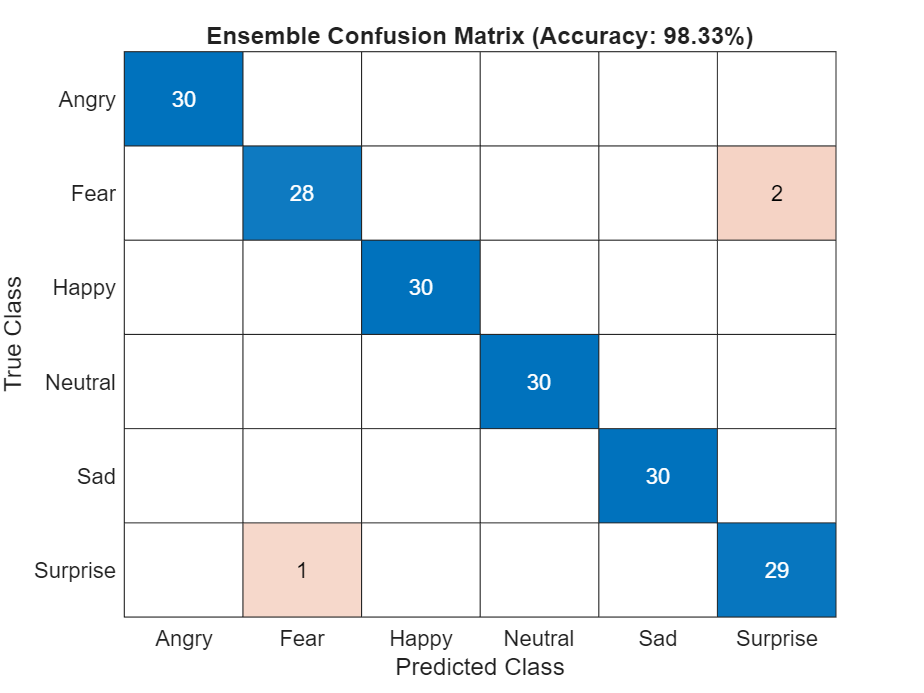

figure;
confusionchart(y_test, pred_ens);
title(sprintf('Ensemble Confusion Matrix (Accuracy: %.2f%%)', acc_ens));

[coeff, score] = pca(features);

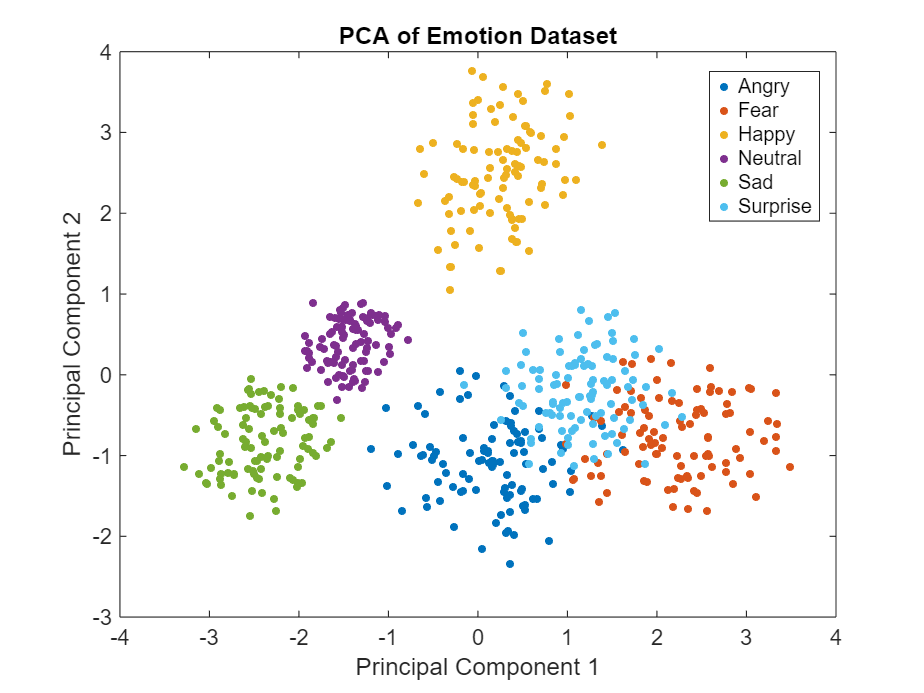

figure;
gscatter(score(:,1), score(:,2), labels);
title('PCA of Emotion Dataset');
xlabel('Principal Component 1');
ylabel('Principal Component 2');

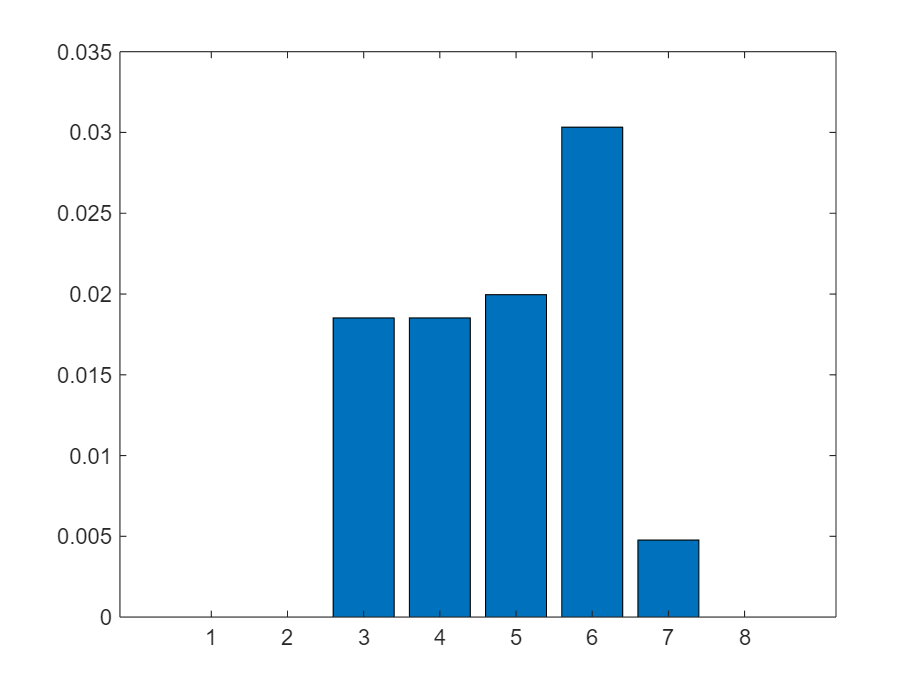

figure;
bar(tree.predictorImportance);

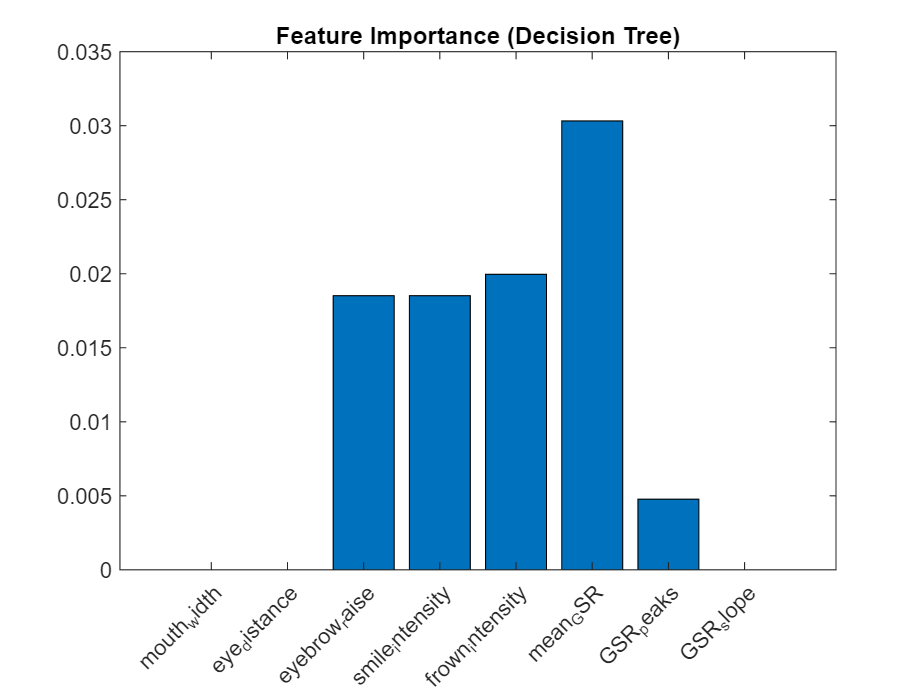

xticklabels(data.Properties.VariableNames(2:end));
xtickangle(45);
title('Feature Importance (Decision Tree)');